Loading the data and model

clear
load('model.mat')
load('data.mat','test_fea','test_gnd','test_size','image_size')

Images

%for i = 1:test_size
%    figure
%    imagesc(reshape(test_fea(i,:),[image_size image_size]))    
%end

Model Prediction

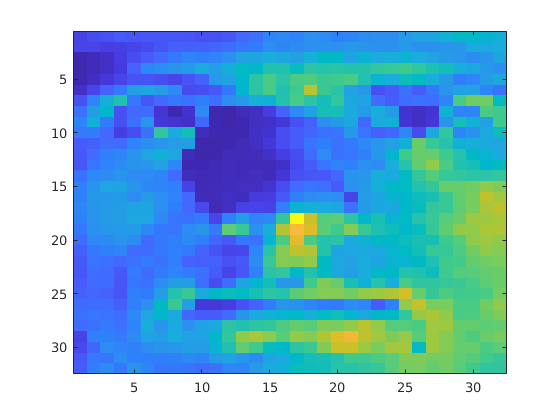

predicted: 30


actual: 30


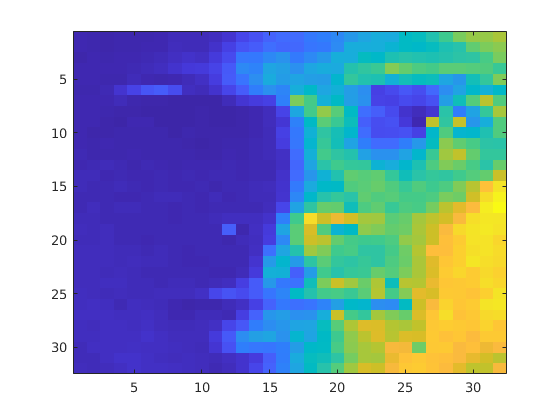

predicted: 30


actual: 30


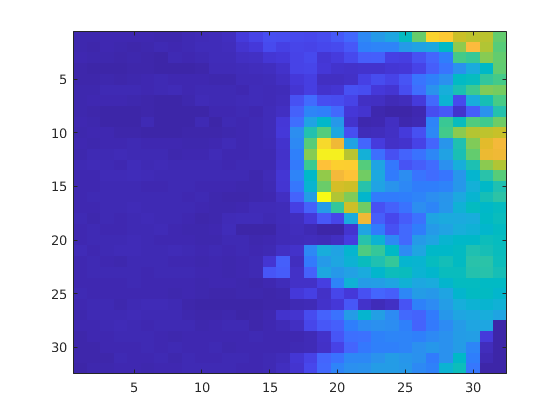

predicted: 36


actual: 36


accuracy=0;
weights = eigen_faces'*(test_fea' - image_mean);
for i = 1:test_size
    pred = predictNN(weights(:,i)',model);
    if pred == test_gnd(i)
        accuracy=accuracy+1;
    end
    figure
    imagesc(reshape(test_fea(i,:),[image_size image_size]))    
    disp('predicted: '+string(pred))
    disp('actual: '+string(test_gnd(i)))
end

disp('accuracy: ' + string(accuracy))

accuracy: 3
